# Lab2 

Ashkan Jafari

810197483

## 1.

### 1.1

#### A)

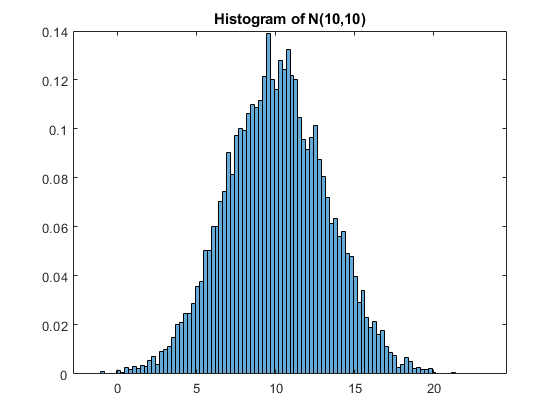

n_bin = 100;
N = 10000;
mean = 10;
variance = 10;
x1 = sqrt(variance) * randn(1,N) + mean;
histogram(x1,n_bin,"Normalization",'pdf');
title 'Histogram of N(10,10)'

#### B)

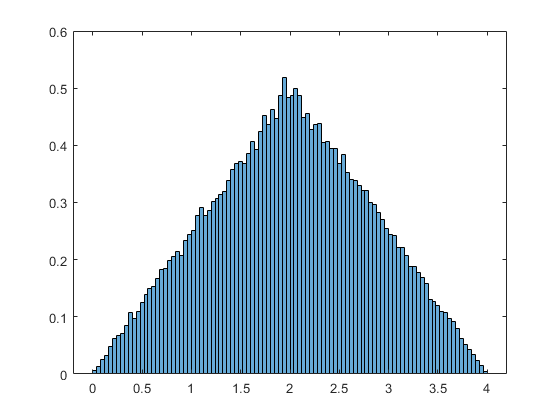

N = 100000;
x2 = rand(1,N+1) * 2;
x3 = x2(2:end) + x2(1:end-1);
histogram(x3,n_bin,"Normalization",'pdf');

If we want to know PDF of the summation of two uniform distributions, we should convolve the two PDFs.

we know that convolution of two step function will produce triangle function.

#### C.

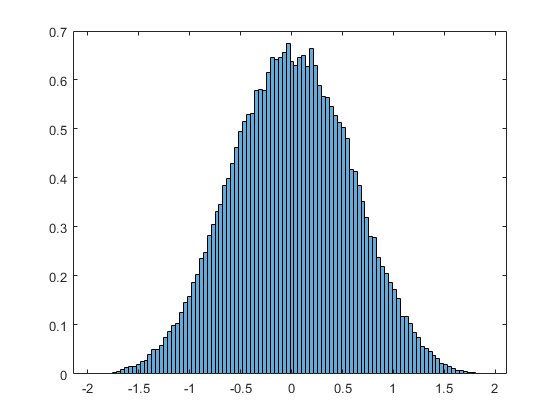

x4 =zeros(1,N);
for i=1:4
    x4 = x4 + (rand(1,N) - 0.5);
end
histogram(x4,n_bin,"Normalization",'pdf')

Just like previous part, convolution of four step function or convolution of two triangle function results this shape.

Based on "CLT", If we sum up a lot of uniform distribution, it will become a normal distribution.

## 2.

### 1

#### A)

N = 101;
n = 0:N;
x = zeros(N+4,1);
x(4) = 1;
y1 = zeros(N+4,1);
for n = 4:N
   y1(n) = 0.5 * y1(n - 1) - 0.25 * y1(n - 2) + x(n) + 2 * x(n - 1) + x(n - 3);
end
a = [1 -0.5 0.25];
b = [1 2 0 1];
y2 = filter(b,a,x)
y1 

As the above results, we could observe the non-filter using algorithm is correct!

stem(y1)

y2 =          0
         0
         0
    1.0000
    2.5000
    1.0000
    0.8750
    0.1875
   -0.1250
   -0.1094


y1 =          0
         0
         0
    1.0000
    2.5000
    1.0000
    0.8750
    0.1875
   -0.1250
   -0.1094


### 2

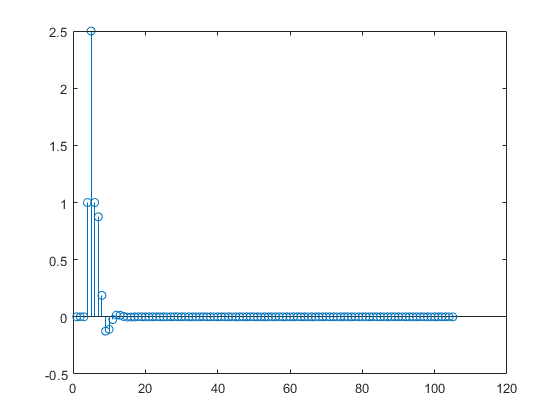

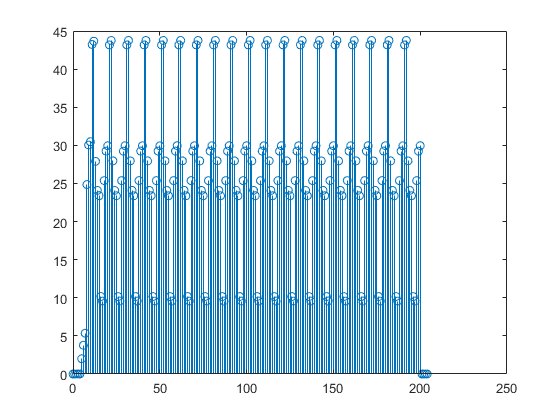

load('PacketsAndHeader.mat');
r = corr_m(hdr_smpl,rx_smpl);

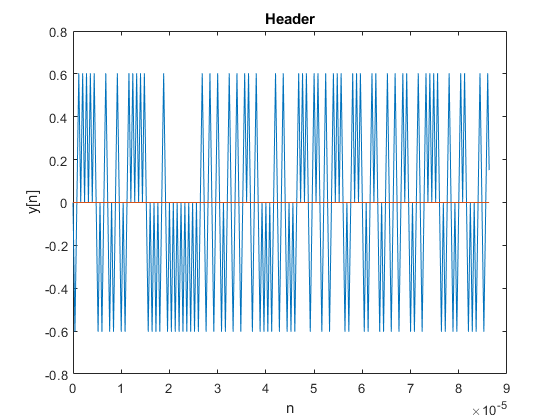

fs = 10e6;
t_header = 0:1/fs:(length(hdr_smpl)-1)/fs;
plot(t_header,real(hdr_smpl),t_header,imag(hdr_smpl));
title('Header')
xlabel('n')
ylabel('y[n]')
t_rx = 0:1/fs:(length(rx_smpl)-1)/fs;
plot(t_rx,abs(rx_smpl))
title('rx_smpl')
xlabel('n')
ylabel('y[n]')

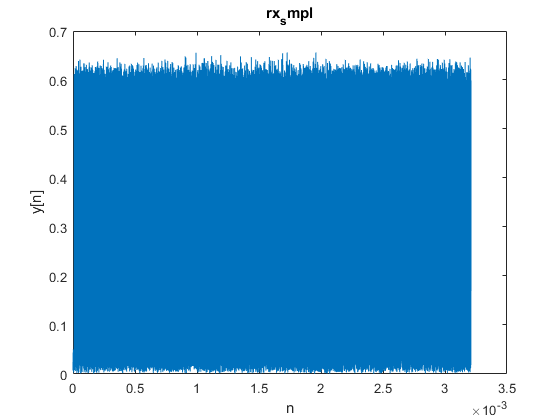

t_r = 0:1/fs:(length(r)-1)/fs;
plot(t_r,abs(r))
title('header and Packets')
ylabel('y[n]')

Delay ~= 1e-5 s

distance = c * D = 300km

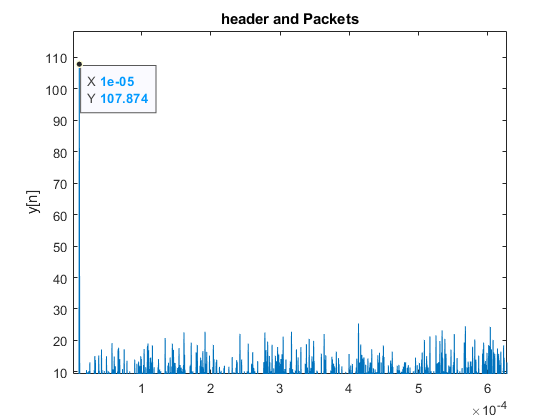

function r = corr_m(x, y)
r = zeros(1, abs(length(y) - length(x)) + 1);
for i=1:length(r)
    r(i) = sum(x.*conj(y(i:i+length(x)-1)));

end
end